# Plotting the single cell values, means and coefficients of variation for a Megatable

clear variables
%% Select the Megatable file
[file,PathName] = uigetfile('*.mat','Select the preprocessed data table');
[path, name]=fileparts(file);

%% Select the parameters
prompt = {'Number of frames:', 'Quantile threshold:', 'Frame limit for the cell exclusion:', 'Time period (sec):', 'Begin of the phase when [H2O2] is minimal:', 'End of the phase when [H2O2] is minimal:', 'Begin of the phase when [H2O2] is maximal:', 'End of the phase when [H2O2] is maximal:', 'Maximal [H2O2] (µM):'};
title = 'Experimental parameters';
lines = 1;
def = {'90','0.3','45', '15', '60', '70', '85', '90', '20'};
answer = inputdlg(prompt, title, lines, def);
assignin('base', 'nb_of_images', answer{1});
assignin('base', 'quantile_threshold', answer{2});
assignin('base', 'frame_limit', answer{3});
assignin('base', 'period', answer{4});
assignin('base', 'min_value_begin', answer{5});
assignin('base', 'min_value_end', answer{6});
assignin('base', 'max_value_begin', answer{7});
assignin('base', 'max_value_end', answer{8});
assignin('base', 'per_conc', answer{9});
% Convert the char variable into numbers
nb_of_images = str2num(nb_of_images);
quantile_threshold = str2num(quantile_threshold);
frame_limit = str2num(frame_limit);
period = str2num(period);
min_value_begin = str2num(min_value_begin);
min_value_end = str2num(min_value_end);
max_value_begin = str2num(max_value_begin);
max_value_end = str2num(max_value_end);
per_conc = str2num(per_conc);

%% Load the experiment data
tic;
filename = char(string(PathName) + string(file));
clearvars file PathName path
load(filename);
table = eval(name);
processed_experiment = name;
clearvars answer def e* filename lines prompt name title

%% Add the folder Functions to the path
addpath('/Users/guillaume/Documents/Matlab/Functions');

%% Creating a matrix with the time
full_time = (period/60) * (nb_of_images - 1);
t = linspace(0,full_time,nb_of_images);
% Transpose t
t = t.';
clearvars nb_of_images full_time;

%% Calculating the value for the last frame of the resting period
resting_period = 2; % This is the duration of baseline recording, in min, before stim.
last_resting_frame = resting_period/(period/60);

%%Calculating the calibrated values of single cell data
% Remove the first column
table(:,1) = [];
% Measure the number of lines and columns
nb_of_images = size(table,1);
nCells = size(table,2);
% Generating matrices
calib_value = zeros(1,nCells);
calib_value_table = zeros(size(table));
per_conc_table(1,1:nCells) = per_conc;
% Calculating min and max for each cell
min_value = mean(table(min_value_begin:min_value_end,:), 1);
min_value_table = repmat(min_value,[nb_of_images 1]);
max_value = mean(table(max_value_begin:max_value_end,:), 1);
% Calculating the calibrated values for each cell
calib_value = per_conc_table./(max_value-min_value);
calib_value_table = repmat(calib_value,[nb_of_images 1]);
calibrated_table = (table-min_value_table).*calib_value;

%% Sorting the cells according to basal calibrated value
% Calculating the basal peroxide concentration for each cell
basal_value = zeros(1,nCells);
basal_value_table = zeros(size(table));
basal_value(1,:) = mean(calibrated_table(1:8,:), 1);
% Cleaning the variables that are no longer useful
clearvars calib_value calib_value_table max_value min_value min_value_table per_conc_table table
% Sorting the data by basal peroxide concentration
clearvars sorting_calibrated_table sorted_calibrated_table
sorting_calibrated_table = zeros(nb_of_images+1,nCells);
sorting_calibrated_table = [basal_value;calibrated_table];
sorted_calibrated_table = sortrows(sorting_calibrated_table.').';
clearvars calib_value calib_value_table calibrated_table 
sorted_calibrated_table_full = sorted_calibrated_table;

%% Cleaning the noisy cells
% This is done by removing cells that exhibit a calibrated value
% higher than the calibration range within the range of time
% 0 - frame_limit
l = 0;
quantile_threshold_low = quantile_threshold

quantile_threshold_low = 0.3000

quantile_threshold_high = 1 - quantile_threshold

quantile_threshold_high = 0.7000

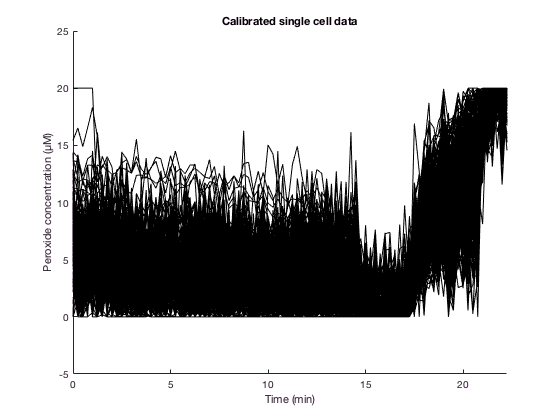

while l<nCells
    l = l+1;
    % Discard the cell if NaN data
    if isnan(sorted_calibrated_table(1,l)) == 1
        sorted_calibrated_table(:,l) = [];
        nCells = size(sorted_calibrated_table,2);
        if l>1
            l = l-1;
        end
    end
    %quantile_low = quantile(sorted_calibrated_table(1:frame_limit,l), quantile_threshold_low)
    if quantile(sorted_calibrated_table(1:frame_limit,l), quantile_threshold_low)<0
        sorted_calibrated_table(:,l) = [];
        nCells = size(sorted_calibrated_table,2);
        if l>1
            l = l-1;
        end
    end
    %quantile_high = quantile(sorted_calibrated_table(1:frame_limit,l), quantile_threshold_high)
    if quantile(sorted_calibrated_table(1:frame_limit,l), quantile_threshold_high)>per_conc
        sorted_calibrated_table(:,l) = [];
        nCells = size(sorted_calibrated_table,2);
        if l>1
            l = l-1;
        end
    end
end

% Dissociating the basal value from the data table
sorted_basal_value = sorted_calibrated_table(1,:);
sorted_calibrated_table(1,:) = [];

%% Deleting values outside of the calibration range
sorted_calibrated_table(sorted_calibrated_table<0) = 0;
sorted_calibrated_table(sorted_calibrated_table>per_conc) = per_conc;
%sorted_calibrated_table(sorted_calibrated_table<0) = NaN;
%sorted_calibrated_table(sorted_calibrated_table>per_conc) = NaN;

%% Plotting the single cell data in 2D
p = figure;
hold on;
Plot_single_data = plot(t, sorted_calibrated_table, 'black');
title({'Calibrated single cell data'});
max_time = max(t);
axis([0 max_time -0.25*per_conc per_conc*1.25])
xlabel({'Time (min)'});
ylabel({'Peroxide concentration (µM)'});
hold off;
saving_name = char(processed_experiment + string('_all data.jpg'));
saveas(p, saving_name);

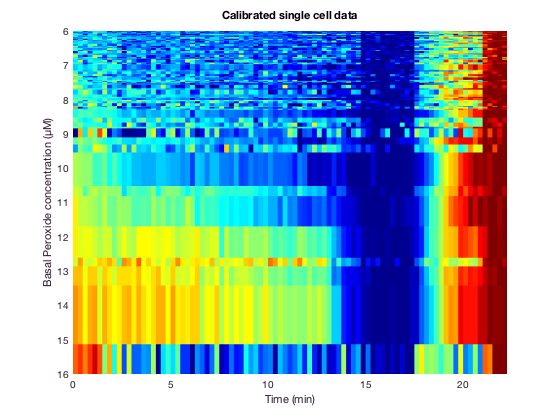


%% Plotting the single cell data sorted by basal peroxide concentration
p = figure;
hold on;
[X,Y] = meshgrid(sorted_basal_value, t);
plot_surf = surf(X,Y,sorted_calibrated_table,'EdgeColor','none');
title({'Calibrated single cell data'});
min_basal_value =  min(sorted_basal_value);
if min_basal_value<0
    min_basal_value = 0;
end
max_basal_value = max(sorted_basal_value);
%axis([min_basal_value max_basal_value 0 max_time 0 per_conc*1.25])
axis([6 16 0 max_time 0 per_conc*1.25])
xlabel({'Basal Peroxide concentration (µM)'});
ylabel({'Time (min)'});
zlabel({'Peroxide concentration (µM)'});
colormap(jet);
view([46.4 40.9])
hold off;
saving_name = char(processed_experiment + string('_all sorted data.fig'));
saveas(p, saving_name);
saving_name = char(processed_experiment + string('_all sorted data_side.jpg'));
saveas(p, saving_name);
hold on;
view([90 90])
hold off;
saving_name = char(processed_experiment + string('_all sorted data_top.jpg'));
saveas(p, saving_name);

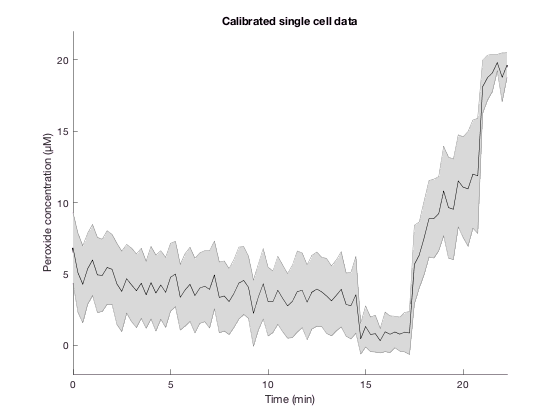


%{
%% Plotting the single cell data sorted by basal peroxide concentration
% Smooth graph
p = figure;
hold on;
double_nCells = 2 * nCells;
double_sorted_basal_value = zeros(1,double_nCells);
% Creating a matrix of sorted basal values with twice more data
% in between point are average of flanking points
for x=1:nCells,
    double_x_minus_05 = 2 * (x - 0.5);
    double_x = 2 * x;
    double_sorted_basal_value(1,double_x_minus_05) = sorted_basal_value(1,x);
    if x<nCells
        double_sorted_basal_value(1,double_x) = (sorted_basal_value(1,x) + sorted_basal_value(1,x+1))/2;
    end
end
% Creating a matrix for the time with twice more points
% Should be using the variables
tt = 0:0.125:22.25;
tt = tt';
% Creating the mesgrid
[Xs,Ys] = meshgrid(double_sorted_basal_value,tt);
Zs = interp2(sorted_basal_value,t,sorted_calibrated_table,double_sorted_basal_value,tt,'spline');
plot_surf = surf(Xs,Ys,Zs,'EdgeColor','none');
%plot_surf = surf(X,Y,sorted_calibrated_table);
%plot_surf = surf(X,Y,'LineStyle', 'none', 'FaceColor', 'interp');
title({'Calibrated single cell data'});
axis([0 max_time 0 per_conc*1.25 0 per_conc*1.25])
xlabel({'Basal Peroxide concentration (µM)'});
ylabel({'Time (min)'});
zlabel({'Peroxide concentration (µM)'});
%colormap(hot);
view(45, 20);
hold off;
%saving_name = char(processed_experiment + string('_all sorted data.jpg'));
%saveas(p, saving_name);
%saving_name = char(processed_experiment + string('_all sorted data.fig'));
%saveas(p, saving_name);
%}

%% Mean and SD
% Generating matrices
mean_table = zeros(nb_of_images,1);
std_table = zeros(nb_of_images,1);
final_cell_number = size(sorted_basal_value,2);
% Calculating the mean (2 refers to column mean)
mean_table = nanmean(sorted_calibrated_table,2);
% Calculating the SD (0 refers to the weight. 0 or 1)
std_table = nanstd(sorted_calibrated_table,0,2);
%Plotting the mean and SD
p = figure;
hold on;
title({'Calibrated single cell data'});
axis([0 max_time -0.1*per_conc per_conc*1.1])
xlabel({'Time (min)'});
ylabel({'Peroxide concentration (µM)'});
Plot2 = plot(t, mean_table, 'Color', 'k', 'LineWidth', 2);
hold on;
Plot(2) = shadedErrorBar(t, mean_table, std_table, '-k');
hold off;
saving_name = char(processed_experiment + string('_mean and sd.jpg'));
saveas(p, saving_name);


%% Distribution plots
% Calculating the last normalised value before normalisation for each cell
last_value = zeros(1,final_cell_number);
start_post_stimulation = frame_limit - last_resting_frame
last_value(1,:) = mean(sorted_calibrated_table(start_post_stimulation:frame_limit,:), 1);
clearvars last_resting_frame start_post_stimulation

%dist_list = {'beta', 'generalized extreme value', 'logistic', 'loglogistic', 'nakagami', 'normal', 'rician', 'weibull', 'kernel'};
dist_list = {'beta', 'nakagami', 'kernel'};
%dist_list = {'kernel'};
min_basal_value_axis = 0*min_basal_value;
max_axis_value_axis = 1.01*max(last_value);


inter_quartile_basal = iqr(sorted_basal_value)

inter_quartile_basal = 1.8188

inter_quartile_post_stim = iqr(last_value)

inter_quartile_post_stim = 1.9050



%Plot as violins
p = figure;
hold on;
title({string(processed_experiment(15:end)) + ' - inter-quartile (basal) = ' + inter_quartile_basal + ' ; inter-quartile (post-stim) = ' + inter_quartile_post_stim});
nm_matrix = zeros(final_cell_number, 2);
nm_matrix(:,1) = (sorted_basal_value)';
nm_matrix(:,2) = (last_value)';
violin(nm_matrix, 'xlabel',{'Basal','Post-Stimulation'},'facecolor',[0 0 1;1 0 0],'mc', '', 'medc', '', 'LineColor', '')

ans =   1×2 Patch array:

    Patch    Patch


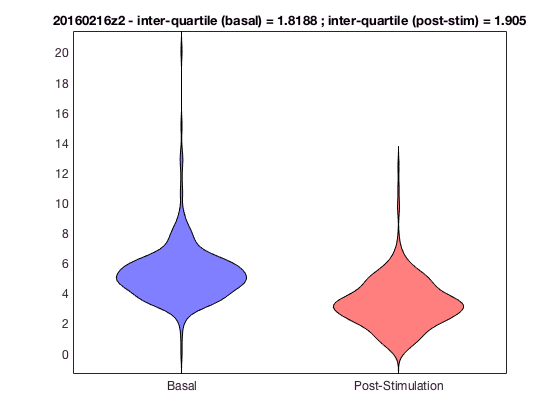

hold off;
saving_name = char(processed_experiment(15:end) + "_violins.jpg");
saveas(p, saving_name);


inter_quartile_basal = iqr(sorted_basal_value)

inter_quartile_basal = 1.8188

inter_quartile_post_stim = iqr(last_value)

inter_quartile_post_stim = 1.9050

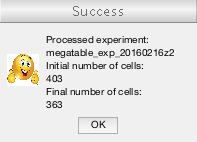


%{
%% Coefficient of variation
% Calculating the coefficient of variation
cv_table = zeros(nb_of_images,1);
cv_table = std_table./mean_table;
%%Plotting the coefficient of variation
p = figure;
hold on;
title({'Coefficient de variation in the field of view'});
cv_median = median(cv_table(1:45,:));
cv_std = nanstd(cv_table(1:45,:));
cv_lim_min = cv_median - cv_std;
cv_lim_max = cv_median + cv_std;
%axis([0 15 cv_lim_min cv_lim_max])
axis([0 15 0.2 1])
xlabel({'Time (min)'});
ylabel({'Coefficient of variation'});
Plot_cv = plot(t, cv_table, 'black', 'LineWidth', 2);
hold off;
saving_name = char(processed_experiment + string('_the_cv.jpg'));
saveas(p, saving_name);
%}

%% Cleaning of the variables
initial_cell_number = size(basal_value_table,2);
final_cell_number = l;
clearvars basal_value basal_value_table cv_lim_max cv_lim_min cv_median cv_std full_name frame_limit l max_time max_value_begin max_value_end mean_table min_value_begin min_value_end nb_of_images nCells per_conc Plot quantile_threshold quantile_threshold_low quantile_threshold_high sorted_basal_value sorting_calibrated_table std_table t X Y

%%Greeting message
myicon = imread('/Users/guillaume/Documents/Matlab/Divers/Great.jpg');
msgbox({'Processed experiment:' num2str(processed_experiment), 'Initial number of cells:' num2str(initial_cell_number), 'Final number of cells:' num2str(final_cell_number)}, 'Success','custom',myicon)